%% D(a) - LQR design for linear system
% specifics for the the problem
M= 1000; %Crane mass
m1= 100; % Load 1 mass
m2= 100; % Load 2 mass
l1= 20;  % Cable length of Load 1
l2= 10;  % Cable length of Load 2
g=  9.81; 

%The A and B values we got from our state space representation
%Substituting the given values of specifics in A and B
A=[0 1 0 0 0 0; 
    0 0 -(m1*g)/M 0 -(m2*g)/M 0;
    0 0 0 1 0 0;
    0 0 -((M+m1)*g)/(M*l1) 0 -(m2*g)/(M*l1) 0;
    0 0 0 0 0 1;
    0 0 -(m1*g)/(M*l2) 0 -(g*(M+m2))/(M*l2) 0];
B=[0; 1/M; 0; 1/(M*l1); 0; 1/(M*l2)];

Cont =  ctrb(A,B)

Cont = 	1.0e+-3 *

         0    1.0000         0   -0.1472         0    0.1419
    1.0000         0   -0.1472         0    0.1419         0
         0    0.0500         0   -0.0319         0    0.0227
    0.0500         0   -0.0319         0    0.0227         0
         0    0.1000         0   -0.1128         0    0.1249
    0.1000         0   -0.1128         0    0.1249         0


if (rank(Cont)==6)
    disp("Rank of ctrb matches order of A, system is controllable")
else
    disp("Rank of ctrb doesnt matche order of A, system is uncontrollable")
end

Rank of ctrb matches order of A, system is controllable


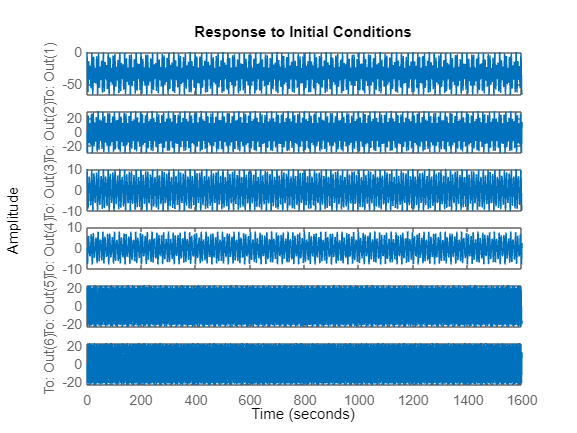

%the initial conditions are as follows.
X_0 = [0;0;10;0;20;0]; 
% We assume the values of Q and R. 
Q=[100 0 0 0 0 0;
   0 100 0 0 0 0;
   0 0 100 0 0 0;
   0 0 0 100 0 0;
   0 0 0 0 100 0;
   0 0 0 0 0 100];
R=0.001;
% Q and R are a part of the cost function that is
% defined in the LQR controller  
% It is an trade-off between Q and R so we use them both to
% develop a system as per our priorities
% Assumption: C matrix is a direct representation of the output
% matrix, which makes D=0
C = eye(6);
D = 0; 
sys1 = ss(A,B,C,D);
% ss is the MATLAB function  for
% calculating the state space representation of the system
figure
initial(sys1,X_0)
%MATLAB inbuilt function to check the initial response of the system
grid on  


disp("When an LQR controller is taken into consideration of system")

When an LQR controller is taken into consideration of system


[K_Gain_mat, Po_def_mat, Poles] = lqr(A,B,Q,R);%In-built MATLAB code for LQR Controllers
K_Gain_mat 

K_Gain_mat =   316.2278  926.8775  -41.7027 -683.4756   44.1102 -334.2650


Po_def_mat  

Po_def_mat = 	1.0e+04 *

    0.0293    0.0380   -0.0216   -0.0606   -0.0106   -0.0330
    0.0380    0.1145   -0.0028   -0.2216    0.0021   -0.1076
   -0.0216   -0.0028    1.3615    0.0184    0.0073   -0.0230
   -0.0606   -0.2216    0.0184    2.9066    0.0458    0.0788
   -0.0106    0.0021    0.0073    0.0458    0.6550    0.0006
   -0.0330   -0.1076   -0.0230    0.0788    0.0006    0.7026


Poles 

Poles =   -0.0161 + 0.7213i
  -0.0161 - 0.7213i
  -0.0298 + 1.0347i
  -0.0298 - 1.0347i
  -0.3838 + 0.3543i
  -0.3838 - 0.3543i


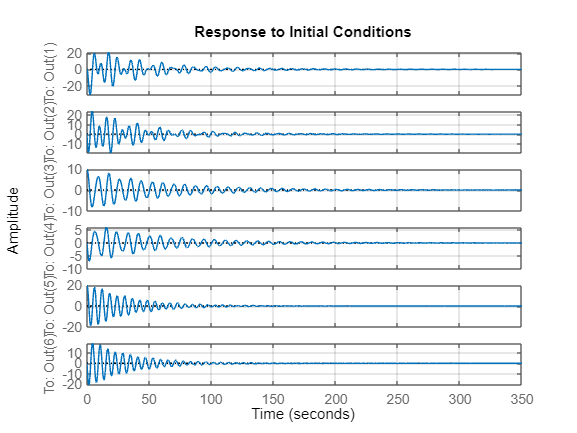

system_2 = ss(A-(B*K_Gain_mat),B,C,D); %Using the K matrix to define ss
figure
initial(system_2,X_0)
grid on

%observation: lower the R value, faster the stabilization
%but the energy consumed is also much higher